# Tarea: Aplicación de PCA a un dataset de vinos

### Juan Uriel Legaria Peña

### Aprendizaje Computacional

Se aplicará PCA al dataset de vinos que puede descargarse en la siguiente página: [https://archive.ics.uci.edu/ml/datasets/wine.](https://archive.ics.uci.edu/ml/datasets/wine.) Solo para recapitular los pasos involucrados en la obtención de componentes principales son (según lo visto en clase);

- Normalizar/Estandarizar los datos.

- Calcular la matriz de covarianzas.

- Descomponer C en vectores propios.

- Ordenar vectores propios en función de los valores propios.

- Seleccionar los k valores mas importantes.

- Construir la matriz de transformación W con los k vectores propios (matriz de proyección).

- Transformar datos X de n-dim con W X de n-dim con W a un espacio nuevo de k-dim, tal que n > k.

### 1.-Preparación de datos

En la primera parte normalizaremos y visualizaremos los datos.

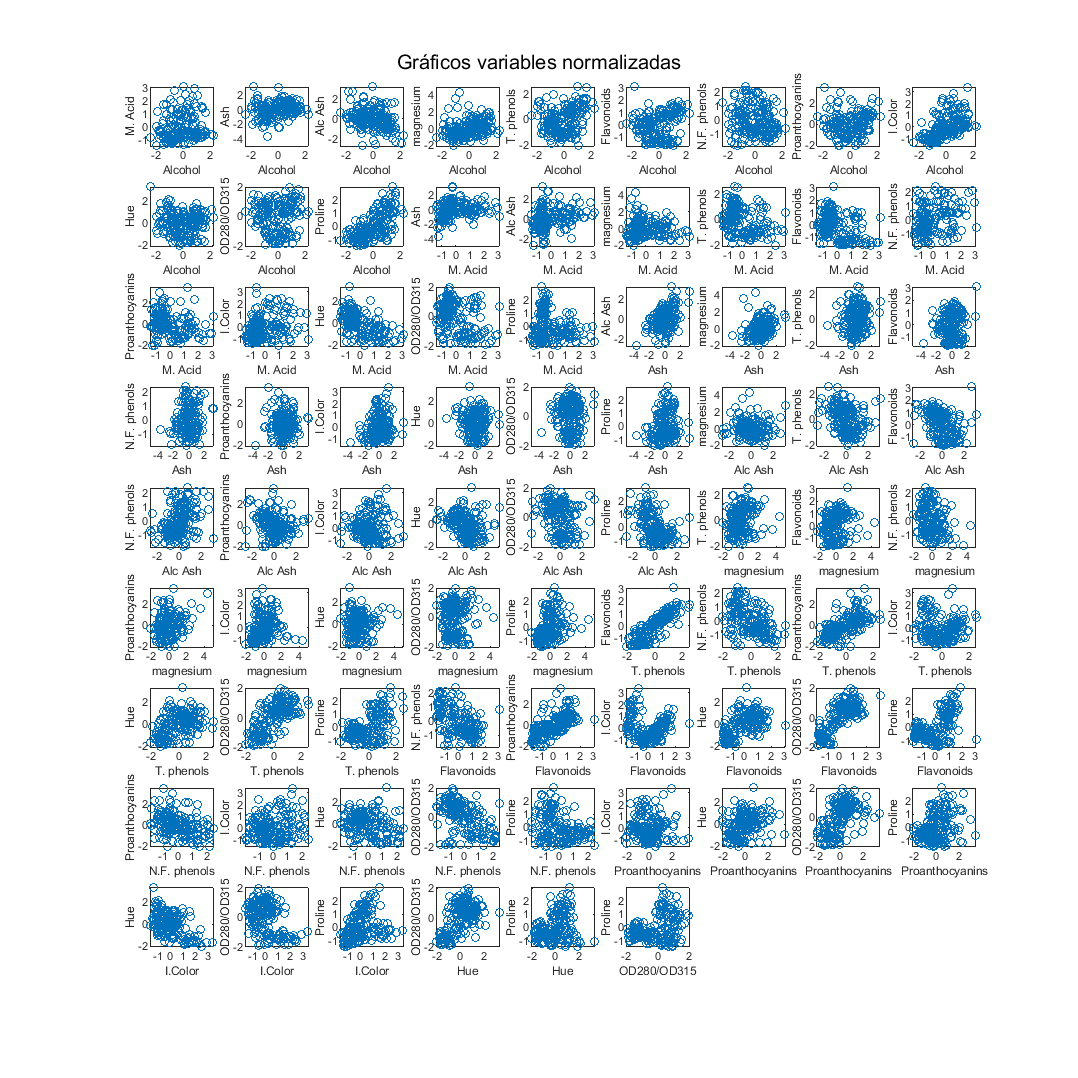

%Importamos los datos
data = importdata('wine.data');
wineClass = data(:,1);
wineData = data(:,2:end);
%Los nombres de las características para hacer los labels de las gráficas.
featureNames = ["Alcohol", "M. Acid", "Ash", "Alc Ash",...
    "magnesium", "T. phenols", "Flavonoids", "N.F. phenols",...
    "Proanthocyanins", "I.Color", "Hue", "OD280/OD315", "Proline"];
%Número de vectores que contiene el dataset
nData = size(wineData, 1);
%Número de descriptores
nFeatures = size(wineData,2);
%Vamos a normalizar y graficar
normalizedData = zeros(nData, nFeatures);
numberOfGraphs = (nFeatures*(nFeatures - 1))/2;
m = floor(sqrt(numberOfGraphs));
n = 0;
if(m^2 < numberOfGraphs)
     n = floor(sqrt(numberOfGraphs)) + 1;
     m = floor(sqrt(numberOfGraphs)) +1;
else
    n = floor(sqrt(numberOfGraphs))
end
%Creamos el precalentador de datos
dataPrecooker = DataPrecook();
graphCounter = 1;
figure()
set(gcf,'units','points','position',[10,10,1200,1200])
sgtitle("Gráficos variables normalizadas")
hold on 
for i = 1:nFeatures
    normalizedX = dataPrecooker.normalize(wineData(:,i));
    normalizedData(:,i) = normalizedX;
    for j = i+1:nFeatures
        
        normalizedY = dataPrecooker.normalize(wineData(:,j));
        subplot(n,m, graphCounter)
        plot(normalizedX, normalizedY, 'o')
        xlabel(featureNames(i))
        ylabel(featureNames(j))
        graphCounter = graphCounter + 1;
    end
end
hold off

Vemos que hay ciertas variables correlacionadas linealmente, como es el caso entre el total de fenoles y los flavonoides. Esto sugiere que hay descriptores que aportan póca información adicional para explicar la variación de los datos, y que podriamos usar PCA para obtener los descriptores que mas aporten a la varianza de los vectores.

### 2.- Obtención de las componentes principales

Aquí crearé una clase para automatizar el proceso de la obtención de las componentes principales.

La obtención de la matriz de covarianzas se hará utilizando la ecuación vista en clase:


$$\textrm{CO}V=\;\frac{\sum_{i=1}^n {\left(X_i -\bar{x} \right)}^T \left(X_i -\bar{x} \right)}{n-1}$$


Aquí  $\bar{x\;}$sería la media de las columnas de la matriz. Y tendriamos que hacer la suma de productos tensoriales indicados por la ecuación anterior. Por suerte MATLAB puede hacer estas operaciones de forma muy conveniente y podemos ahorrarnos el desarrollo por componentes.

%Obtenemos la matriz de covarianzas
pcaAnalyzer = PCAAnalyzer();
covarianceMatrix = pcaAnalyzer.getCovarianceMatrix(normalizedData);
%Vamos a obtener los eigenvalores y eigenvectores ya ordenados
%Ademas la función implementada realiza un gráfico de barras como el que
%vimos en clase

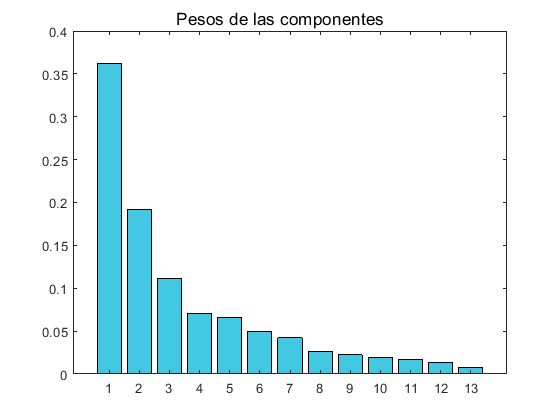

[eigValues, eigVectors] = pcaAnalyzer.getComponents(covarianceMatrix);

### 3.- Proyección de los datos

Vamos a proyectar los datos en las primeras dos componentes unicamente. Estas explican el siguiente porcentaje de la varianza de los datos:

(eigValues(1)/sum(eigValues) + eigValues(2)/sum(eigValues))*100

ans = 55.4063

Usemos nuestro analizador pca para proyectar.

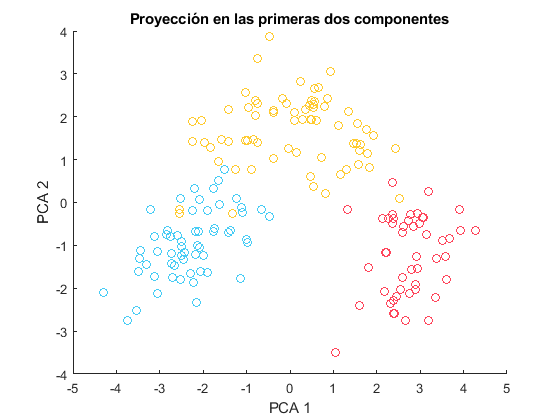

projectedData = pcaAnalyzer.projectData(normalizedData, 2, eigVectors);
color1 = "#47ccf5";
color2 = "#ffcb30";
color3 = "#ff455b";
figure()
title("Proyección en las primeras dos componentes")
hold on 
for i = 1:nData
    point = projectedData(i,:);
    if(wineClass(i) == 1)
        plot(point(1), point(2), 'o', 'color', color1)
    elseif(wineClass(i) == 2)
        plot(point(1), point(2), 'o', 'color', color2)
    elseif(wineClass(i) == 3)
        plot(point(1), point(2), 'o', 'color', color3)
    end
end
hold off
xlabel("PCA 1")
ylabel("PCA 2")